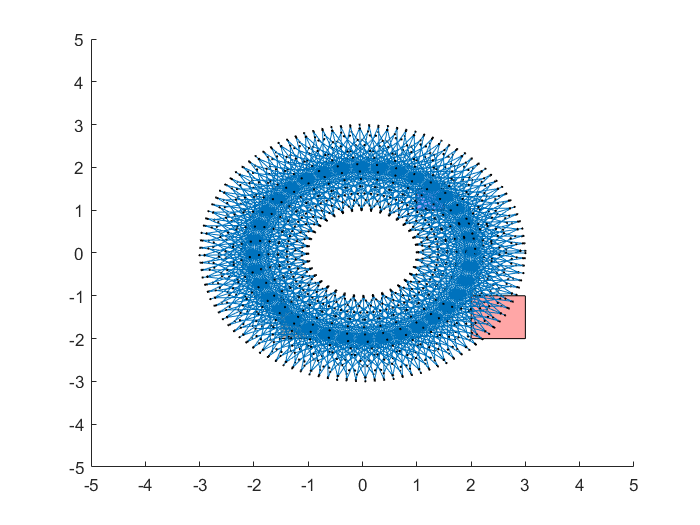

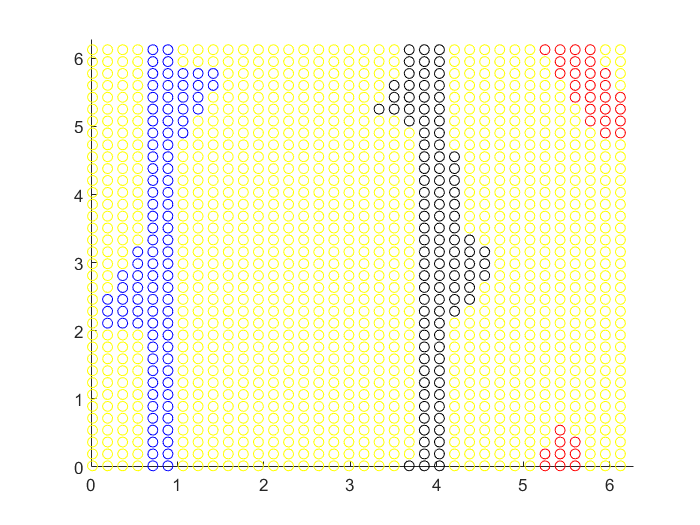

clc;
close all
clear all

f1 = figure; % for torus
f2 = figure;  % for c space


p1 = polyshape([2 2 3 3],[-2 -1 -1 -2]);
p2 = polyshape([1 1;1.5 1;1.5 1.5;1,1.5]);
p3 = polyshape([-1.5 -1;-1 -2;-1.5 -2]);


x1 = 2;% link1 has 2 units length
y1=  0;
x2 = 3; % link 2 has 1 unit length
y2 = 0;

figure(f1)
axis([-5 5 -5 5]);
hold on
%  line([0,x1],[0,y1]);
line([x1,x2],[y1,y2]);
scatter(x2,y2,1,'black')
% scatter(x1,y1,1,'black')


plot (p1,'FaceColor','red');
plot(p2,'FaceColor','blue');
plot(p3,'FaceColor','black');

for th1 = 1:10:360
    for th2 = 1:10:360
        % calculating points
        x1 = 2*cos(th1*pi/180);
        y1 = 2*sin(th1*pi/180);
        x2 = x1 + 1*cos(th2*pi/180);
        y2 = y1 + 1*sin(th2*pi/180);
        
        % plotting end poit of the arm
        figure(f1)
        line([x1,x2],[y1,y2]);
        scatter(x2,y2,1,'black')
        
        pause (0.01);
        
        
        % c space
        figure(f2)
        axis([0 2*pi 0 2*pi]);
        hold on
        
        % calculating equations/points of arms
        line1_x = linspace(0,x1);
        line1_y = line1_x*(y1/x1);
        line2_x = linspace(x1,x2);
        m = (y1 - y2)/(x1 - x2);
        line2_y = line2_x*m + (y1 - m*x1);
        
        % obtacles
        p1 = transpose([2 -2; 2 -1; 3 -1; 3 -2; 2 -2]);
        p2 = transpose([1 1;1.5 1;1.5 1.5;1 1.5; 1 1]);
        p3 = transpose([-1.5 -1;-1 -2;-1.5 -2;-1.5 -1 ]);
        
        % checking if line is inside polygon or not
        [in, ~] = inpolygon(line1_x, line1_y, p1(1,:), p1(2,:));
        p1_1 = find(in,1,'first');
        [in2, ~] = inpolygon(line2_x, line2_y, p1(1,:), p1(2,:));
        p1_2 = find(in2,1,'first');
        
        [in, ~] = inpolygon(line1_x, line1_y, p2(1,:), p2(2,:));
        p2_1 = find(in,1,'first');
        [in2, ~] = inpolygon(line2_x, line2_y, p2(1,:), p2(2,:));
        p2_2 = find(in2,1,'first');
        
        [in, ~] = inpolygon(line1_x, line1_y, p3(1,:), p3(2,:));
        p3_1 = find(in,1,'first');
        [in2, ~] = inpolygon(line2_x, line2_y, p3(1,:), p3(2,:));
        p3_2 = find(in2,1,'first');
        
        if  numel(p1_1) ~= 0 ||  numel(p1_2) ~= 0
            scatter(deg2rad(th1),deg2rad(th2),'red');
        elseif numel(p2_1) ~= 0 ||  numel(p2_2) ~= 0
            scatter(deg2rad(th1),deg2rad(th2),'blue');
        elseif numel(p3_1) ~= 0 ||  numel(p3_2) ~= 0
            scatter(deg2rad(th1),deg2rad(th2),'black');
        else
            scatter(deg2rad(th1),deg2rad(th2),'yellow');
        end
        
        
        
    end
end